clear all ;clc;
addpath('Convex_src/');
addpath(fullfile('Convex_src/minFunc'));
addpath(fullfile('Convex_src/minFunc_2012'));
addpath(fullfile('Convex_src/minFunc','compiled'));
addpath(fullfile('Convex_src/minFunc','mex'));
addpath('Non_convex_src/');

table = zeros(20,20);
% filename = sprintf('Phase_transitions');
L = 80;
for i = 1:20
    for j = 1:20
        N = 2*i;
        K = 2*j;
        for k = 1:1
            %%% Matrices B and C %%%
            C = randn(L,N)/sqrt(L);
            idx2 = randperm(L);
            idx2 = idx2(1:K);
            B = speye(L);
            B = B(:,idx2); % Sparse
%           S2 = S2(:,1:n2); % Short

            %%% Random vectors %%%
            m = randn(N,1);
            m = m/norm(m);
            h = randn(K,1);
            h = h/norm(h);
            
            %%% Convolution %%%
            conv_wx = real(ifft(fft(C*m).*fft(B*h)));
            [M,H] = blindDeconvolve(conv_wx,C,B,4);

            [UM,SM,VM] = svd(M,'econ');
            [UH,SH,VH] = svd(H,'econ');

            [U2,S2,V2] = svd(SM*VM'*VH*SH);
            mEst=sqrt(S2(1,1))*UM*U2(:,1);
            hEst=sqrt(S2(1,1))*UH*V2(:,1);

            table(i,j) = norm(m*h'-mEst*hEst','fro')/norm(m)/norm(h);        
       end
    end
end

|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 9.59e-05 | 1.00e+04 |    0  |    0  |
|  2   | 3.34e-08 | 1.00e+04 |    0  |    0  |
|  3   | 2.13e-08 | 1.00e+04 |    0  |    0  |
|  4   | 6.02e-09 | 1.00e+05 |    0  |    0  |
elapsed time: 0 seconds
|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 1.14e-04 | 1.00e+04 |    0  |    0  |
|  2   | 2.20e-07 | 1.00e+04 |    0  |    0  |
|  3   | 1.72e-08 | 1.00e+04 |    0  |    0  |
|  4   | 9.61e-09 | 1.00e+04 |    0  |    0  |
elapsed time: 0 seconds
|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 1.37e-04 | 1.00e+04 |    0  |    0  |
|  2   | 6.11e-07 | 1.00e+04 |    0  |    0  |
|  3   | 2.38e-08 | 1.00e+04 |    0  |    0  |
|  4   | 2.2

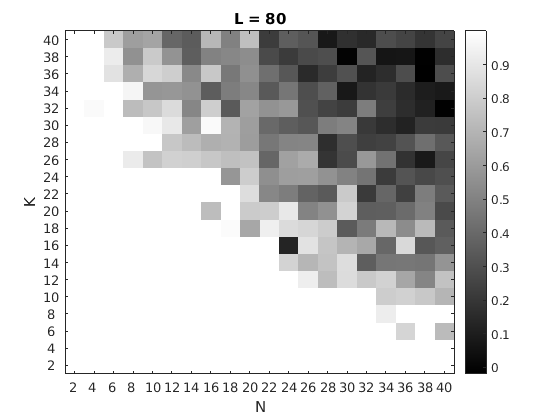

imagesc(1-table);
set(gca,'YDir','normal');
colormap gray
title('L = 80');
xlabel('N')
ylabel('K')
set(gca,'xtick',[1:20],'xticklabel',[2:2:40])
set(gca,'ytick',[1:20],'yticklabel',[2:2:40])
colorbar

warning('off','all')
warning

All warnings have the state 'off'.


global A B y L h x
table = zeros(20,20);
L = 80;
for i = 1:20
    for j = 1:20
        N = i*2;
        K = j*2;
        F = dftmtx(L)/sqrt(L);
        B = F(:,1:K);
        h = randn(K,1);
        h = h/norm(h);
        C = randn(L,N)+1i*randn(L,N);
        A = F*C;
        x = randn(N,1);
        x = x/norm(x);
        y =diag(B*h*x'*A');
        w = 1;
        [u,v] = nonConvexBD(w,x,y,B,C,L,N,K,2000);
        table(i,j) = norm(h*x' - u*v','fro')/norm(h*x','fro');
    end
end

 
Calling SDPT3 4.0: 324 variables, 84 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 84
 dim. of socp   var  = 243,   num. of socp blk  = 81
 dim. of linear var  = 81
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.3e+01|9.5e+00|1.7e+04| 2.634120e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.720|2.0e-05|2.7e+00|2.4e+03| 4.718216e+02 -3.776872e+00| 0:0:00| chol  1  1 
 2|1.000|0.925|1.2e-05|2.1e-01|4.1e+02| 3.136270e+02 -1.014310e+00| 0:0:00| chol  1  1 
 3|0.991|1.000|9.3e-07|7.0e-04|3.3e

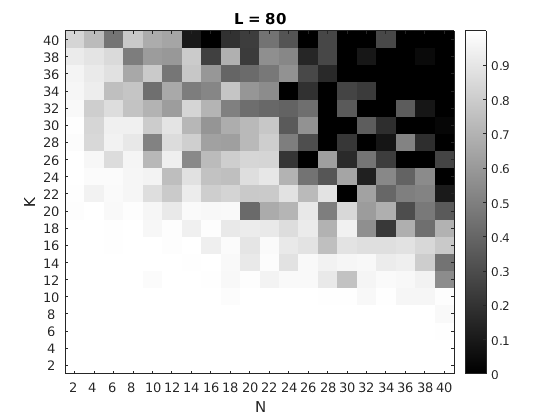

for i = 1:20
    for j = 1:20
        if table(i,j) > 1.0
            table(i,j) = 1.0;
        end
    end
end
imagesc(1-table);
set(gca,'YDir','normal');
colormap gray
title('L = 80');
xlabel('N')
ylabel('K')
set(gca,'xtick',[1:20],'xticklabel',[2:2:40])
set(gca,'ytick',[1:20],'yticklabel',[2:2:40])
colorbar